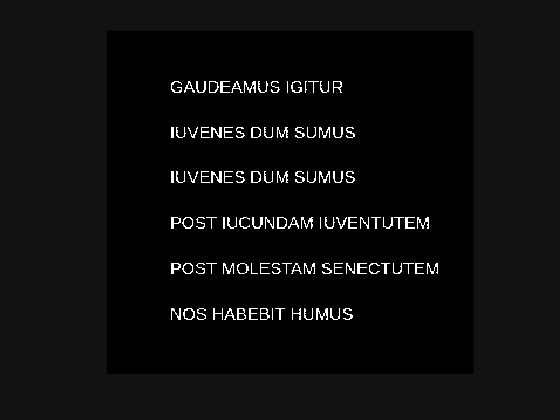

%tarea 1
% Leer imagen y pasar a double (Práctica 3)
img_rgb = imread('imagen1.jpg');
img_d = im2double(img_rgb);

% Convertir a escala de grises manual (Práctica 3, Ejercicio C)
R = img_d(:,:,1); G = img_d(:,:,2); B = img_d(:,:,3);
img_gray = 0.3*R + 0.59*G + 0.11*B;

% Binarización con umbral (Tarea 1)
umbral = 0.5; % Ajustar según la iluminación
img_bw = img_gray < umbral; % Inversión: texto blanco (1), fondo negro (0)
imshow(img_bw);

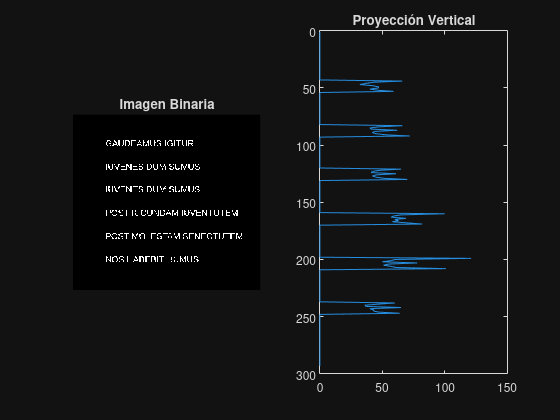

% tarea 2
% calcula la proyección vertical es decir suma todos los píxeles de cada
% fila.
proy_v = sum(img_bw, 2); 
figure;
subplot(1,2,1); imshow(img_bw); title('Imagen Binaria');
subplot(1,2,2); plot(proy_v, 1:size(img_bw,1)); 
set(gca, 'YDir', 'reverse'); title('Proyección Vertical');

%encontrar dónde hay texto  lo que hace es buscar donde la suma es mayor que cero
% usa un pequeño umbral por si hay ruido
umbral_filas = 2; 
filas_con_texto = proy_v > umbral_filas;
% detectar cambios porque pasar de negro a blanco es el inicio y pasar de blanco a negro es el fin
cambios = diff([0; filas_con_texto; 0]);
inicios_f = find(cambios == 1);
fines_f = find(cambios == -1) - 1;
fprintf('Se han detectado %d filas de texto.\n', length(inicios_f));

Se han detectado 6 filas de texto.


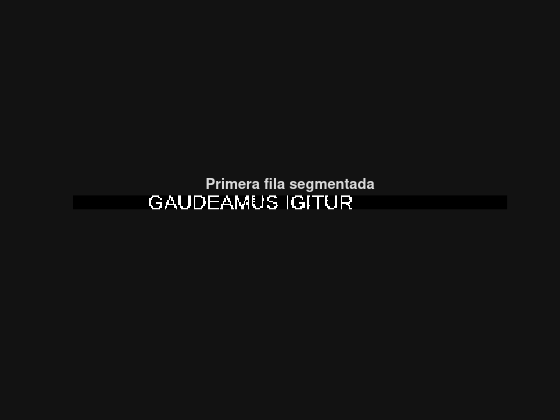

if ~isempty(inicios_f)
    primera_fila = img_bw(inicios_f(1):fines_f(1), :);
    figure; imshow(primera_fila); title('Primera fila segmentada');
end